**Immagine Nulla:** g = 0

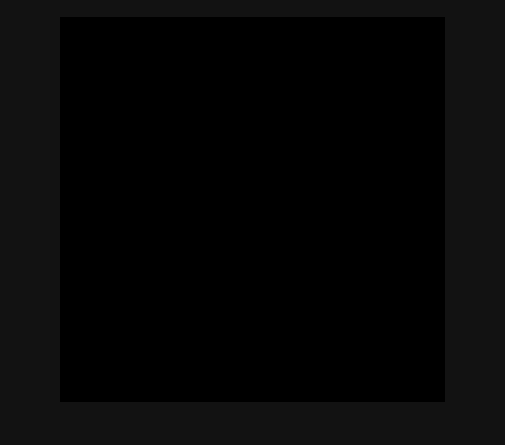

I_black = zeros(512,512);
imshow(I_black)

**Immagine completamente bianca:** g = 255

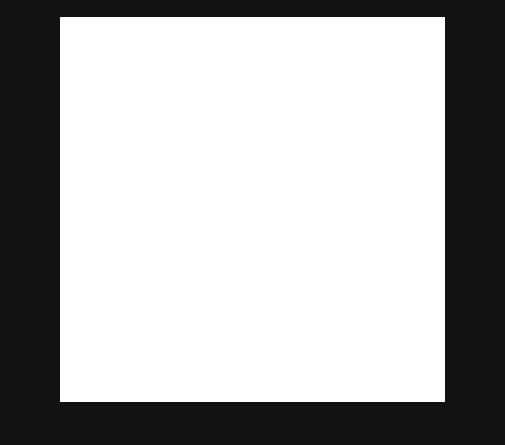

I_white = 255 * ones(512,512);
imshow(I_white)

**Immagine scalata, k = 2. **Saturazione sul bianco

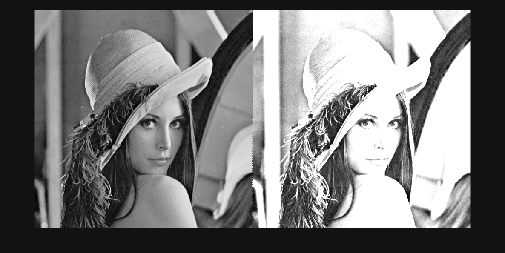

I = imread("imgs/lena.png");
I = rgb2gray(I);
I_scaled = min(2 * I, 255);
imshowpair(I,I_scaled,"montage")

**Minimo / Massimo tra due immagini** (pixel per pixel)

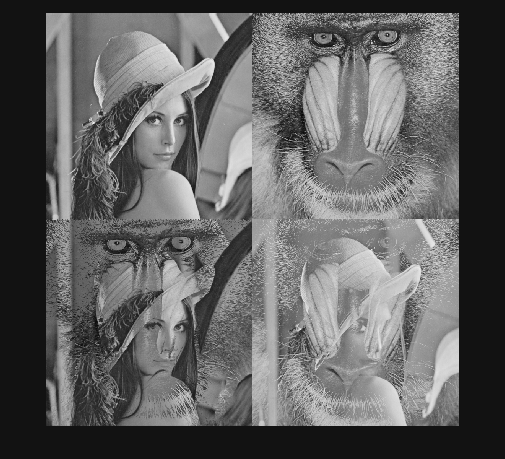

I2 = imread("imgs/baboon.png");
I2 = rgb2gray(I2);
I_min = min(I,I2);
I_max = max(I,I2);
montage({I,I2,I_min,I_max});

**Media semplice**

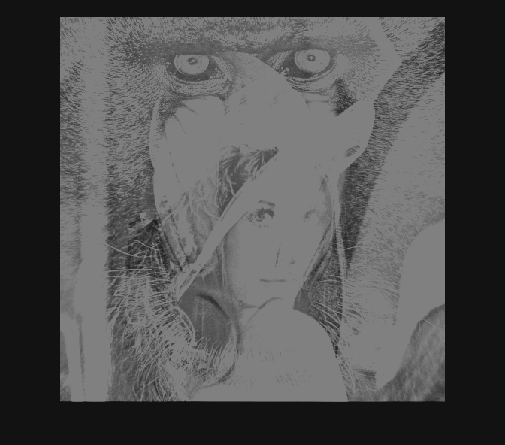

I_avg = (I + I2) / 2;
imshow(I_avg)

**Blend tra immagini con fattore alpha.**  

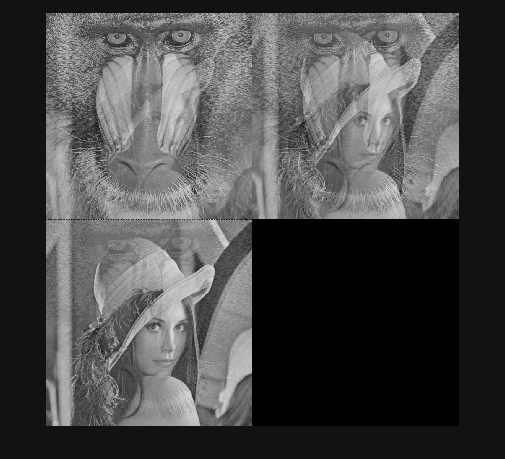

alpha=0.25;
I_blend1 = alpha * I + (1 - alpha) * I2;
alpha=0.50;
I_blend2 = alpha * I + (1 - alpha) * I2;
alpha=0.75;
I_blend3 = alpha * I + (1 - alpha) * I2;
montage({I_blend1,I_blend2,I_blend3})